# Product Identification

This example shows three ways to determine the MathWorks products used by a code base and pros and cons of each.

### Install and License (or Trial)

For these approachs, install and license a MATLAB or get a trial for all tools that might be used.

## License-Based

### Start Fresh MATLAB

First, start a fresh MATLAB so no products are checked out.  We can verify this by calling `license('unuse')` to verify.

license inuse

matlab


### Run The Code

This function will check out Signal Processing Toolbox on even days of the month and Image Processing on odd days.

I'm even, using Optim

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


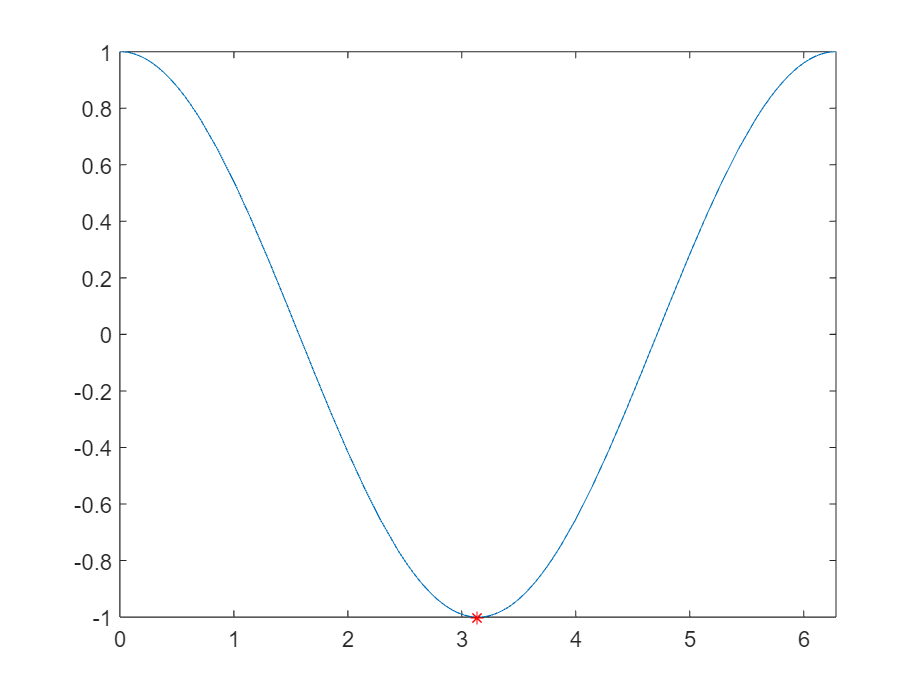

optimEvenImageOdd

This function uses Communications Toolbox.

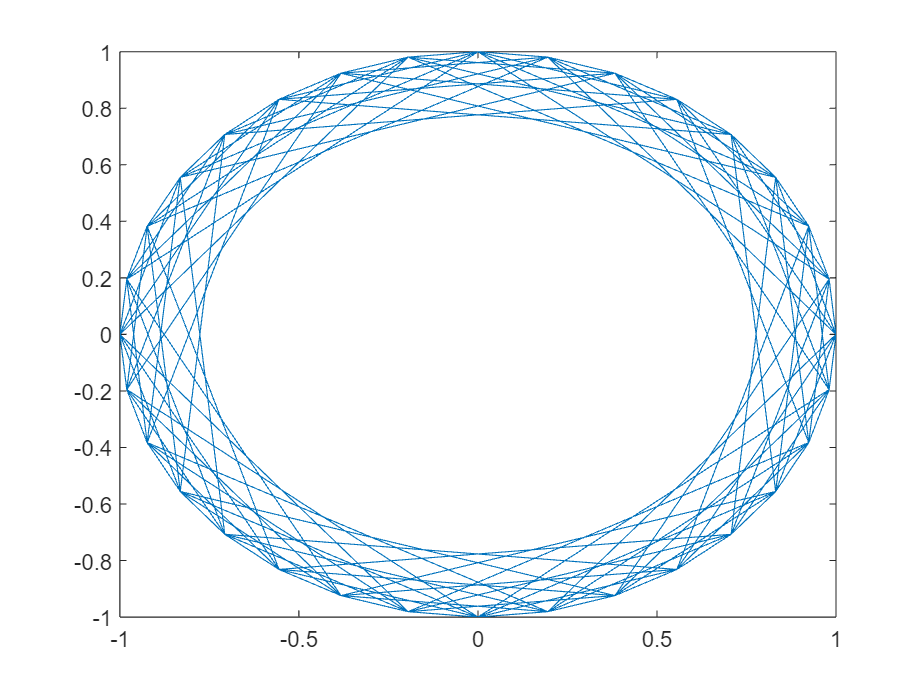

figure
stepSomething

### See What Was Used

license inuse

communication_toolbox
matlab
optimization_toolbox
signal_blocks
signal_toolbox


### Results

We can see it captures the toolboxes used by the run but not the one that runs on the off even/odd day.  Since Communications Toolbox depends on Signal and DSP, those show up in the list.

#### Pros

- This will definitively tell you whether a toolbox was used.

- Shows dependendent toolboxes.

#### Cons

- You need to have the toolboxes installed and licensed.

- You need to have coverage on all toolboxes.  From this example, we can see that it does not appear one of the two is necessary because that portion of the code was not run.

## Project-Based

### Create Project

If you're not already using projects, create a project that contains your code base.  The easiest way will likely to be "Project from Folder" where the folder contains the code base.  You can throw the project away later if you don't choose to continue using it or if you want to further modularize it.

[https://www.mathworks.com/help/matlab/matlab_prog/create-projects.html](https://www.mathworks.com/help/matlab/matlab_prog/create-projects.html)

### Run Project Dependency Analysis

You can now run the project dependency analysis from the project tab.  On the right-hand side, it will show you the dependent products, and if you select them it will point to the lines where they're used so you can see the functions or blocks in use.

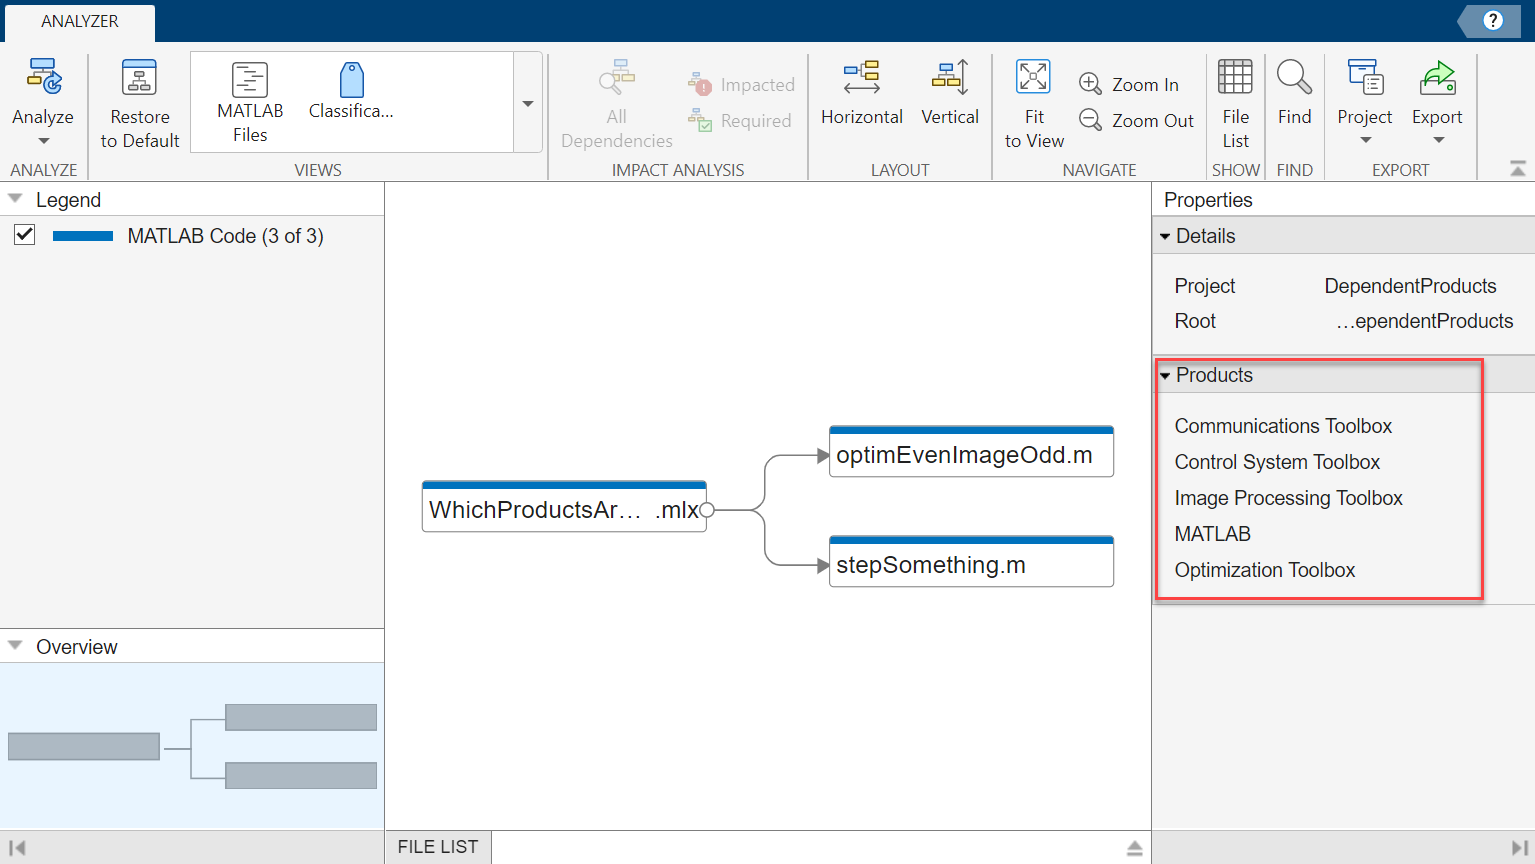

We can see that this captures all of the products used by this project.  However, it's running a static analysis.  When it sees the `step()` function in `stepSomething()`, it associates it to the Control System Toolbox's `step` but in this case it's actually the `step` method of the `comm.CPFSKModulator` object and thus does not need Control System Toolbox.  Additionally, the static analysis can miss things that are obfuscated by something like `feval` or other means for invoking a function.

### Results

We can see it does capture all products used but also gives a false positive.

#### Pros

- More likely to capture all products statically without needing to execute the code or get coverage.

- Works on large code bases.

#### Cons

- You need to have the toolboxes installed and licensed.

- Does not show dependent products.  On a trial or quote, these would be automatically added.

- Can give false positives because the analysis is static.

## File-Based

### Run `requiredFilesAndProducts`

You can run the following function with a list to get required products: [https://www.mathworks.com/help/matlab/ref/matlab.codetools.requiredfilesandproducts.html](https://www.mathworks.com/help/matlab/ref/matlab.codetools.requiredfilesandproducts.html)

[~,products] = matlab.codetools.requiredFilesAndProducts(["stepSomething" "optimEvenImageOdd"]);
products = struct2table(products)

products = 14×4 table
                       Name                         Version     ProductNumber    Certain
    ___________________________________________    _________    _____________    _______
    {'MATLAB'                                 }    {'9.13' }           1          true  
    {'Control System Toolbox'                 }    {'10.12'}           3          true  
    {'Image Processing Toolbox'               }    {'11.6' }          17          true  
    {'Antenna Toolbox'                        }    {'5.3'  }         141          false 
    {'Curve Fitting Toolbox'                  }    {'3.8'  }          60          false 
    {'Deep Learning HDL Toolbox'              }    {'1.4'  }         179          false 
    {'Fixed-Point Designer'                   }    {'7.5'  }          91          false 
    {'System Identification Toolbox'     

### Results

We can see it does not capture all products, gives a "Certain" to Controls and gives lots of "uncertain" false positives.  It is uncertain about Optimization which is present.  In general, I do not recommend this approach over projects' dependency analysis.

#### Pros

- Minimal overhead for a small number of files.

#### Cons

- Misses things inside of `feval` et al.

- You need to have the toolboxes installed and licensed.

- Can give false positives because the analysis is static.  

- Can be uncertain about required products.

- Need to provide individual file or list of files.